clear

addpath('matlab_functions\')

#### Compare FEM and analytical solution

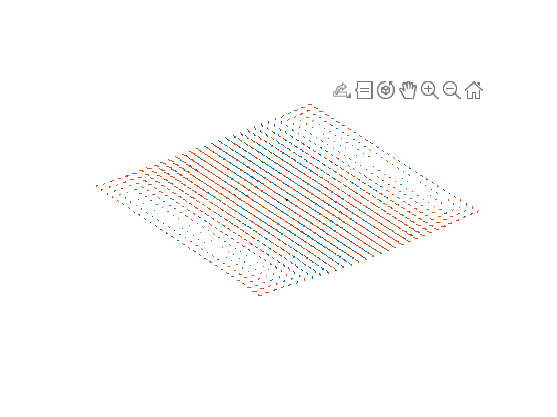

Model = myModel;
freq = 100; % (Hz)
mesh_size = 5; % 1:finest 9:coarsest

lim = 30e-3;
[x,y,z] = ndgrid( ...
    linspace(-lim, lim, 31), ...
    linspace(-lim, lim, 31), ...
    -1.5e-3);

Model = ComsolInterface('Build', Model);
ComsolInterface('PlotGeometry', Model);

tic
ComsolInterface('Solve', Model, freq, mesh_size);
toc

Elapsed time is 123.603257 seconds.


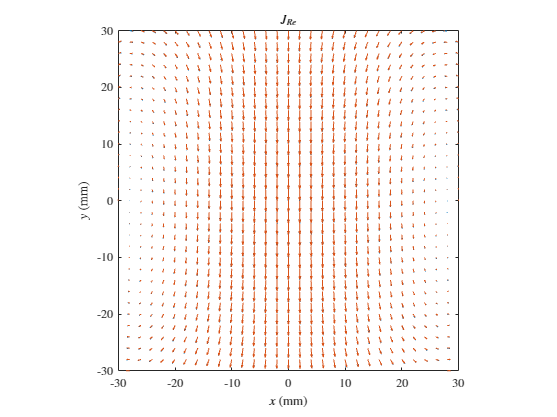

error: 3.41772%

[J1x,J1y] = ComsolInterface('InterpField', Model, {'Jx' 'Jy'}, x,y,z);

coilAbovePlate = CoilAbovePlate3D(Model.coil, Model.layers, 'TruncateWidth',Model.comsol.truncate_width);
[J2x,J2y] = coilAbovePlate.EvaluateField({'Jx' 'Jy'}, x,y,z, 2*pi*freq);

CompareField(x,y, real(J1x),real(J1y), real(J2x),real(J2y), '$J_{Re}$')

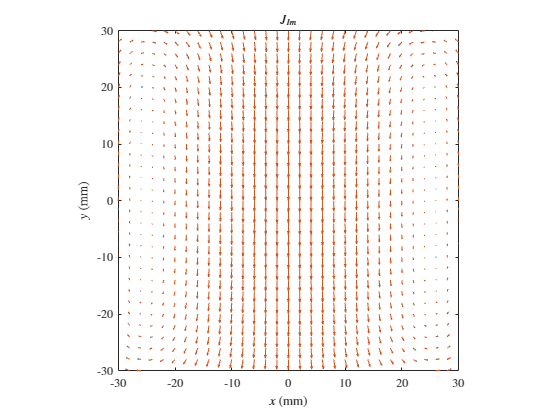

error: 1.49721%

CompareField(x,y, imag(J1x),imag(J1y), imag(J2x),imag(J2y), '$J_{Im}$')

function CompareField(x,y, E1x,E1y, E2x,E2y, titlestr)

x_ = unique(x);
E_ = [reshape(E1x,1,[]); reshape(E1y,1,[])];
scale = (x_(2) - x_(1)) * 1e3 / max(vecnorm(E_));

figure
hold on
quiver(x*1e3, y*1e3, E1x*scale, E1y*scale, 'off')
quiver(x*1e3, y*1e3, E2x*scale, E2y*scale, 'off')
xlim([min(x,[],'all') max(x,[],'all')] * 1e3)
ylim([min(y,[],'all') max(y,[],'all')] * 1e3)
axis square
box on
title(titlestr, 'Interpreter','latex')
xlabel('$x$ (mm)', 'Interpreter','latex')
ylabel('$y$ (mm)', 'Interpreter','latex')

error = sqrt((E1x-E2x).^2 + (E1y-E2y).^2);
base = sqrt(E1x.^2 + E1y.^2);

fprintf("error: %g%%", mean(error) / mean(base) * 100)

end